Definicja funkcji meromorficznej $F\left(s\right)$:

syms s

% zera
zeros = [1, 0.5];
poles = [2, -1, -0.5, -0.75];

num = 1;
for index = 1:length(zeros)
    num = num * (s - zeros(index));
end

den = 1;
for index = 1:length(poles)
    den = den * (s - poles(index));
end

F = num / den;

fprintf("Ilość zer Z = %d", length(zeros));

Ilość zer Z = 2

fprintf("Ilość biegunów B = %d", length(poles));

Ilość biegunów B = 4

Definicja konturu $C$:

w = 0:0.01:2*pi;
p = 3 * cos(w);
q = 3 * sin(w);

Wyrysowanie konturu oraz zer i biegunów.

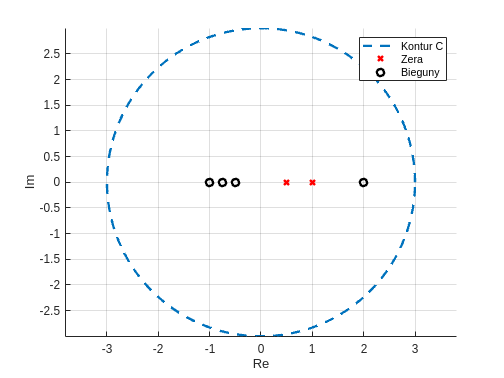

figure();
grid on;
hold on;
axis equal;
legend("show");
xlabel("Re");
ylabel("Im");

plot(p, q, "LineWidth", 2, "LineStyle", "--", "DisplayName", "Kontur C");
plot(real(zeros), imag(zeros), "rx", "LineWidth", 2, "DisplayName", "Zera");
plot(real(poles), imag(poles), "ko", "LineWidth", 2, "DisplayName", "Bieguny");

Wyznaczenie obrazu konturu po przekształceniu przez funkcję $F\left(s\right)$:

c = p + q*1i;
k = double(subs(F, s, c));

Wyrysowanie przekształconego konturu:

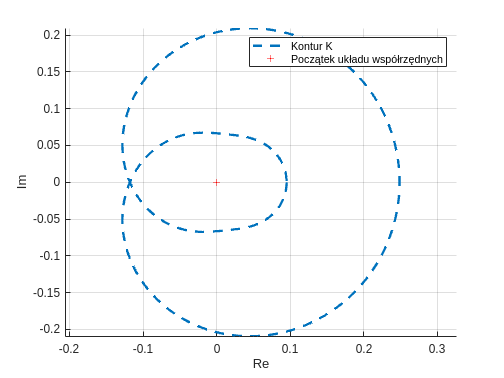

figure();
grid on;
hold on;
axis equal;
legend("show");
xlabel("Re");
ylabel("Im");

plot(real(k), imag(k), "LineWidth", 2, "LineStyle", "--", "DisplayName", "Kontur K");
plot(0, 0, "r+", "DisplayName", "Początek układu współrzędnych");

fprintf("Ilośc okrżęń wokół początku układu współrzędnych Z - B = %d", length(zeros) - length(poles));

Ilośc okrżęń wokół początku układu współrzędnych Z - B = -2

Wizualizacja liczenia obrotów krzywej $K$w okół początku układu współrzędnych.

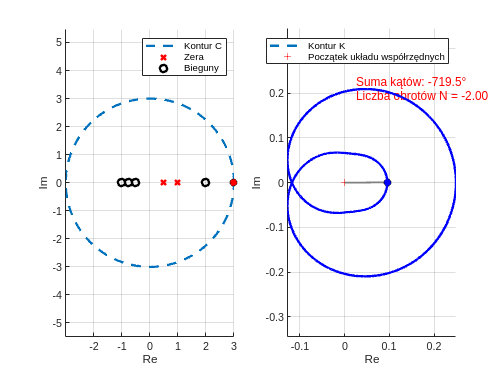

figure();

subplot(1, 2, 1);
grid on;
hold on;
axis equal;
legend("show");
xlabel("Re");
ylabel("Im");

plot(p, q, "LineWidth", 2, "LineStyle", "--", "DisplayName", "Kontur C");
plot(real(zeros), imag(zeros), "rx", "LineWidth", 2, "DisplayName", "Zera");
plot(real(poles), imag(poles), "ko", "LineWidth", 2, "DisplayName", "Bieguny");
h_s_point = plot(p(1), q(1), "ko", "MarkerFaceColor", "r", "HandleVisibility", "off");

subplot(1, 2, 2);
grid on;
hold on;
axis equal;
legend("show");
xlabel("Re");
ylabel("Im");

plot(real(k), imag(k), "LineWidth", 2, "LineStyle", "--", "DisplayName", "Kontur K");
plot(0, 0, "r+", "DisplayName", "Początek układu współrzędnych");

h_line = line([0, real(k(1))], [0, imag(k(1))], "Color", [0.5 0.5 0.5], "LineWidth", 1.5, "HandleVisibility", "off");
h_g_point = plot(real(k(1)), imag(k(1)), "ko", "MarkerFaceColor", "b", "HandleVisibility", "off");
h_text = text(max(real(k))*0.1, max(imag(k)), "", "FontSize", 10, "Color", "r", "HandleVisibility", "off");
total_angle = 0;
for index = 2:length(p)
    % Obliczanie wektorów względem punktu (0, 0)
    vec_prev = [real(k(index-1)); imag(k(index-1))];
    vec_curr = [real(k(index)); imag(k(index))];
    
    % Wyznaczenie zmiany kąta
    delta_angle = atan2(vec_curr(2), vec_curr(1)) - atan2(vec_prev(2), vec_prev(1));
    
    % Korekta przeskoku (wrapping)
    if delta_angle > pi
        delta_angle = delta_angle - 2*pi;
    end
    if delta_angle < -pi
        delta_angle = delta_angle + 2*pi;
    end
    
    total_angle = total_angle + delta_angle;
    
    % Aktualizacja wizualizacji
    set(h_s_point, "XData", p(index), "YData", q(index));
    set(h_g_point, "XData", real(k(index)), "YData", imag(k(index)));
    set(h_line, "XData", [0, real(k(index))], "YData", [0, imag(k(index))]);
    
    % Wyświetlanie aktualnego stanu N
    N = total_angle / (2*pi);
    set(h_text, 'String', sprintf('Suma kątów: %.1f°\nLiczba obrotów N = %.2f', rad2deg(total_angle), N));
    
    % Rysowanie ścieżki
    plot([real(k(index-1)) real(k(index))], [imag(k(index-1)) imag(k(index))], "b-", "LineWidth", 2, "HandleVisibility", "off");
    
    drawnow;
    pause(0.01);
end